# Explore Machine Learning Models with the Classification-Learner

In this script, we will demonstrate a workflow to test many different algorithms and hyperparameters if you want to compare and test the results of many different machine learning setups.

For the code in this livescript to work it is important that you ran the 

### Creating a Classification Model

We are now ready to create our classification model. Choosing which type of machine learning algorithm and how best to handle the parametrization of that algorithm depends on many factors such as the amount of data, the number of features, hardware limitations, and many others. The MATLAB documentation page on [Machine Learning Models](https://www.mathworks.com/discovery/machine-learning-models.html) provides a high level overview of many different types of models and reasons why one might choose to use each one. The following figure demonstrates just a few of the types of models that you can build with MATLAB. 

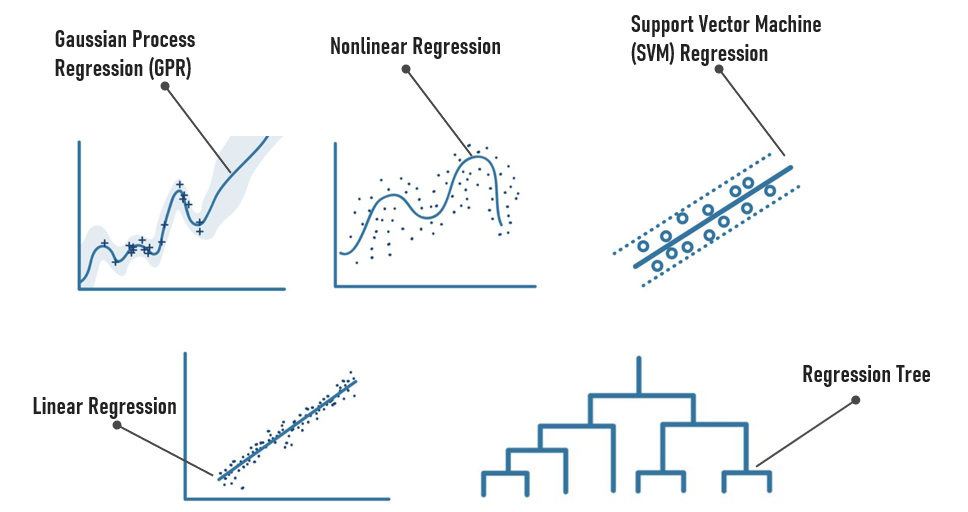

The k-nearest neighbor algorithm is perhaps one of the simplest machine learning algorithms to understand. The documentation page on [classification using nearest neighbors](https://www.mathworks.com/help/stats/classification-using-nearest-neighbors.html)  offers a good high-level overview and explanation on the topic. 

In order to understand the knn algorithm, Let's imagine a dataset with three distinct groups and two features (such that it can be easily visualized on an x-y axis) as follows. 

#### Figure 1.) Plotting the Dataset by Group Type

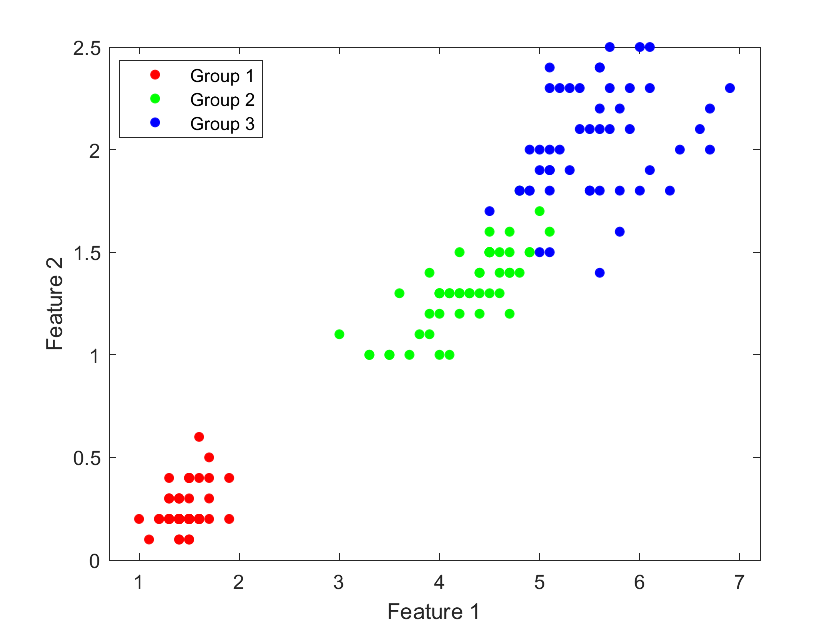

where the different colors represent different output labels. Now, in order to classify a new point, we would simply take a look at what label the closest n data points carry, with n being a parameter that we can set ("numNeighbors for our function in MATLAB). 

If our new data point is marked by the black X, then the circled data points are the closest points to that new data point.

#### Figure 2.) Plotting a New Point and Its Closest Points

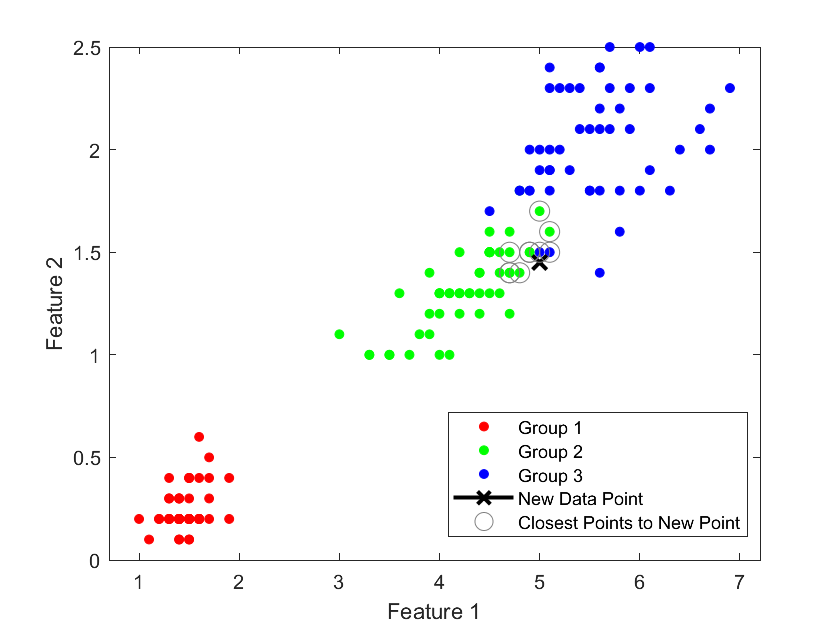

The model would then predict that the new data point should have the same label as the data points that are closest to it, in this case the category corresponding to green. It's important to note a few things. First, this example used just two features  while other datasets may have many more features (like ours). Additionally, one can change the distance metric used. The most common might be the Euclidean distance, but in MATLAB we offer many other possible metrics, which can [be revisted here](https://www.mathworks.com/help/stats/classification-using-nearest-neighbors.html).

### Creating a Classification Model: Classification Learner App

Often we want to test many different models and compare their performance. We can do so by using several useful prebuilt applications in MATLAB.

The first one to note is the [Classification Learner application](https://www.mathworks.com/help/stats/classificationlearner-app.html). Given that we already have the data in a format that is suitable to feed into most machine learning model generating functions in MATLAB, we can call the following function to open up the classification learner app and automatically feed it the domain and response data that we used.

classificationLearner(signalDataSplitted(1:1200,:),labelsEachSecond(1:1200,:))

This will open up the following screen, where we can confirm that the domain and response variables are the ones that we want. 

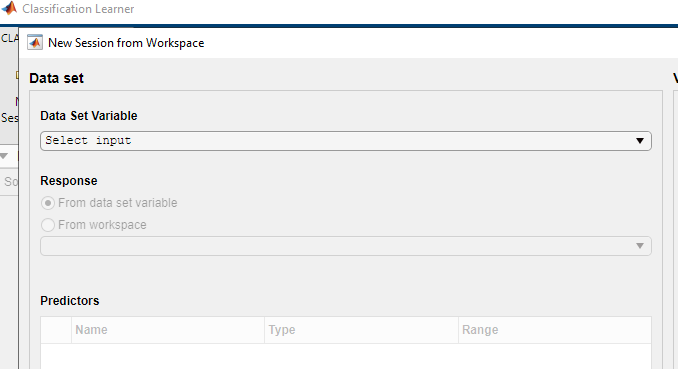

Simply clicking "Start Session" will then give us the following window. Note the toolbar on the top, where if we click the downward arrow next to the "Fine Tree" and "Medium Tree" tab we get the following drop down. This contains a listing of all the different types of models that we could train. 

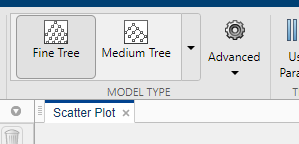

If we click "All" and then hit "Train", we can see that this application will immediately load our data into each type of model and give us the validation accuracy that the model represents. On the left hand side we can see a queue of all the models the application has trained and is planning to train, as well as the accuracy of the already trained models. 

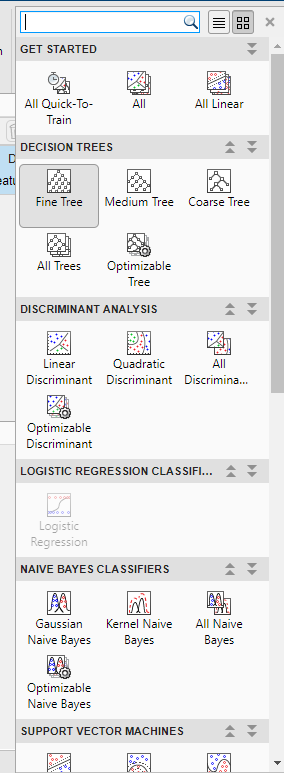

As we can see, this tool is a great way to quickly and easily train many different types of learning models given the same dataset. We can set up the application to test out all the different types of models, all without any further fiddling on the user's end. Additionally, you can see a list of the possible hyperparameters to play with for each model in our documentation [here](https://www.mathworks.com/help/stats/hyperparameter-optimization-in-classification-learner-app.html). You can manually adjust some parameters if you want to see how it will affect the performance of the model, though also keep in mind that the Classification Learner App does some optimization the hyperparameters automatically. You can adjust the hyperparameters by hitting the "Advanced" gear icon next to the model type tab that we used earlier, and then click "Advanced" again to bring up a dialog box with some input options for hyperparameters.